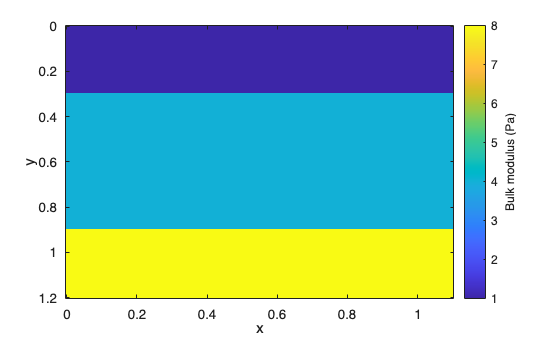

clear
close all
clc

% Spatial computational grids
domain_x = [0,1.1]; Nx=151;
domain_y = [0,1.2]; Ny=161;

grid_x_primal = Grid1DUnifPrimal(domain_x,Nx);
grid_y_primal = Grid1DUnifPrimal(domain_y,Ny);
grid_x_dual   = Grid1DUnifDual(grid_x_primal);
grid_y_dual   = Grid1DUnifDual(grid_y_primal);

gsp_P  = GridSpace2D(grid_x_primal, grid_y_primal);
gsp_Vx = GridSpace2D(grid_x_dual,   grid_y_primal);
gsp_Vy = GridSpace2D(grid_x_primal, grid_y_dual);

% Medium
medium = AcousticMedium2D.layeredY( ...
    BetaValues=[1,0.5,0.25], ...
    KappaValues=[1,4,8], ...
    Domain=[domain_x;domain_y], ...
    RelativeWidths=[0.25,0.5,0.25]);
[kappa,beta_x,beta_y,wspeed,cMax] = sampleMedium2D(gsp_P,medium);

kappa.plot;

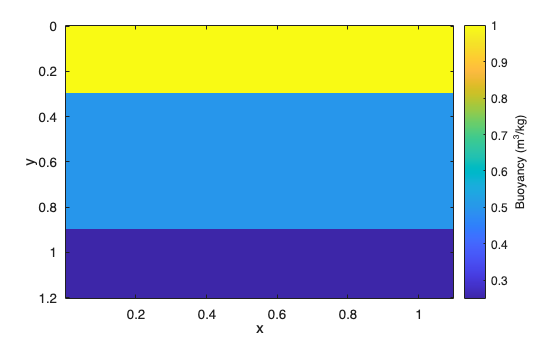


beta_x.plot;

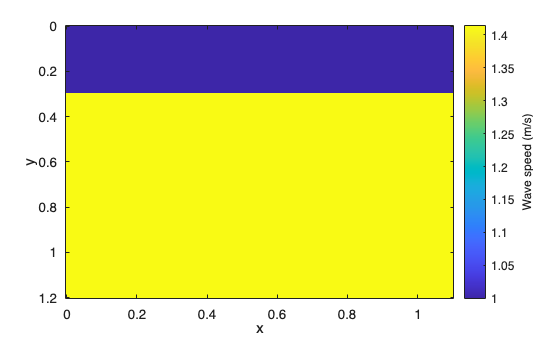


wspeed.plot;


% Time grid
domain_t = [0,1];
CFL = 0.9;
dt = CFL*(6/7)/(cMax*sqrt(sum(1./gsp_P.h.^2)));
Nt = ceil(diff(domain_t)/dt)+1;
dt = diff(domain_t)/(Nt-1); %recomputing dt to ensure time length is divisible by dt
times = domain_t(1):dt:domain_t(2);

% Define two pressure multipoles
% An order-zero pressure monopole at (0.35,0.45).
monopole = MultipoleTerm2D( ...
    [0.35,0.45],[0,0], ...
    @(t) exp(-((t-0.10)/0.025).^2), ...
    Amplitude=1,TargetField="pressure");

% An x-derivative of delta at (0.65,0.55). The factor multiplying the
% dipole is proportional to the grid spacing so that its discrete strength
% is visually comparable with that of the monopole.
xDipole = MultipoleTerm2D( ...
    [0.65,0.55],[1,0], ...
    @(t) exp(-((t-0.18)/0.035).^2), ...
    Amplitude=gsp_P.h(1),TargetField="pressure");

% Construct the multipole collection and discretize it on the three
% staggered computational grids.
multipole = MultipoleSource2D( ...
    [monopole,xDipole],ApproximationOrder=4);
source = multipole.discretize( ...
    gsp_P,gsp_Vx,gsp_Vy);

% Four-sided PML and solver
pml = PML2D( ...
    WidthLeft=0.15,WidthRight=0.15, ...
    WidthBottom=0.15,WidthTop=0.15, ...
    ReflectionCoefficient=1e-6, ...
    PolynomialDegree=3);

% Output grid and times
gsp_out = GridSpace2D( ...
    Grid1DUnifPrimal(domain_x,101), ...
    Grid1DUnifPrimal(domain_x,101));

times_out = linspace(domain_t(1),domain_t(2),81);

solver = AcousticSolver2D_PML( ...
    gsp_P,times, ...
    gsp_out,times_out, ...
    medium,pml, ...
    SpatialOrder=4);

% Zero initial pressure and velocity
p0 = @(x,y) zeros(size(x));
vx0 = @(x,y) zeros(size(x));
vy0 = @(x,y) zeros(size(x));

% Run the solver
[P,Vx,Vy] = solver.solve(p0,vx0,vy0,Source=source);

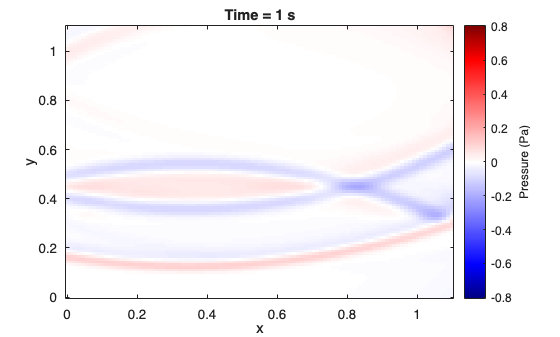

% Animate pressure
ax = axes(figure(Name="Pressure generated by 2D multipoles"));
P.animate(Parent=ax,relLimFactor=0.1);

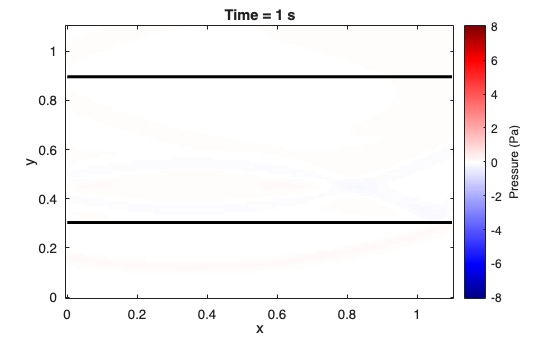

P.animateMedBack(medium,NumContours=11);